Testing and plotting SIFT features

num =   SIFTPoints with properties:

          Scale: 3.4358
    Orientation: 0
         Octave: 0
          Layer: 3
       Location: [206.2893 15.1828]
         Metric: 0.0942
          Count: 1


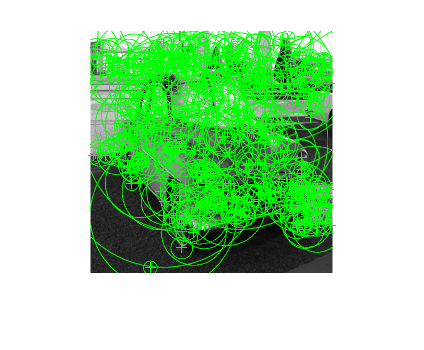

Creating table 1/2
	Projecting data...
	35179 buckets
	min / max size: 1 / 1503
	mean / median: 1.691350e+00 / 1
Creating table 2/2
	Projecting data...
	36624 buckets
	min / max size: 1 / 1957
	mean / median: 1.624618e+00 / 1
Total time: 0.961942


Retrieving candidates from table 1
	-----> 0.178707 seconds
Retrieving candidates from table 2
	-----> 0.132583 seconds
Removing duplicate candidates...
	-----> 0.005308 seconds
Performing knn search...
	-----> 0.008211 seconds
Calculating candidate sizes...
	-----> 0.005076 seconds


Unrecognized function or variable 'queryM'.

I = im2gray(imread("car2.jpg"));

I = imresize(I, [256 256]);
sift = detectSIFTFeatures(I);
figure, imshow(I), hold on;
% plot(sift.selectStrongest(3))
[features, valid_points] = extractFeatures(I, sift);
plot(valid_points,'showOrientation',true);


%CIFAR100
% rootFolder = 'cifar-100-matlab\CIFAR-100\TEST';
% categories = {'cup','dinosaur','forest','hamster'};

%COREL80
rootFolder = 'CorelDB';
categories = {'pet_dog','sc_sunset','wl_buttrfly','wl_deer'};

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imds.ReadFcn = @readFunctionTrain;

% Change the number 50 to as many training images as you would like to use
% how does increasing the number of images change the 
% accuracy of the classifier?
imagesPerClass = 10
[trainingSet, ~] = splitEachLabel(imds, imagesPerClass, 'randomize'); 

featureSet = [];
ref = [];
numImages = numel(trainingSet.Files);

% preprocess the images in the dataset and collect:
% - their SIFT features into the featureSet matrix
% - their original image ID into the ref vector
for i = 1 : numImages
    I = im2gray(readimage(trainingSet,i));
    I = imresize(I, [256 256]); % can try without this
    sift = detectSIFTFeatures(I);
    [features, sift_points] = extractFeatures(I, sift);
    featureSet = [featureSet features.'];
    ref = [ref repmat([i], 1, size(features,1))];
end


% construct LSH hash tables for featureSet

% Tune hyperparameters
Q = 31;   % # of queries
K = 32;   % # of nearest neighbors to search for each query
L = 2;    % # of tables
M = 10;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(featureSet, L, M, W);


% query an input image
% [idsSIMPLE, cand_sizeSIMPLE, binsFound_ratiosSIMPLE] = lshSearch(Qfeatures, X, lshStruct, K);
[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(F(:, 1:Q), F, lshStruct, K, T);


% convert the feature IDs into their original image IDs
oriImages = zeros(size(idsMULTIPROBE));
for i = 1 : size(idsMULTIPROBE, 1)
    for j = 1 : size(idsMULTIPROBE, 2)
        if idsMULTIPROBE(i, j)>0
          oriImages(i,j) = ref(:,idsMULTIPROBE(i, j));
        end
    end
end

% aggregate and weight the image features by their ranks 
uniqImageIds = unique(oriImages);
N = numel(uniqImageIds);
weights = zeros(N,1);

for k = 1 : N
%   count(k) = sum(sum(oriImages==uniqImageIds(k)));
%   exp(N-k+1)
%   count(k) = exp(N - k + 1) * sum(sum(oriImages == uniqImageIds(k)));
%   count(k) = sum((K + (0 : K - 1) * -1) * (oriImages == uniqImageIds(k)));
  weights(k) = sum(flip(exp(1 : K)) * (oriImages == uniqImageIds(k)));
end

ranks = sortrows([weights uniqImageIds], 1, 'descend')


% display all the matching images
for pic = 1:length(ranks)
    if ranks(pic,2)>0
        I = readimage(trainingSet, ranks(pic, 2));
        figure, imshow(I);
    end
end
